# Image Stitching

In this example, feature-based techniques are used to automatically stitch together a set of images. The procedure for image stitching is an extension of feature-based image registration. Instead of registering a single pair of images, multiple image pairs are successively registered relative to each other to form a panorama.

To get started, please run the code below to select the "Concrete Registration" folder included in your course files.

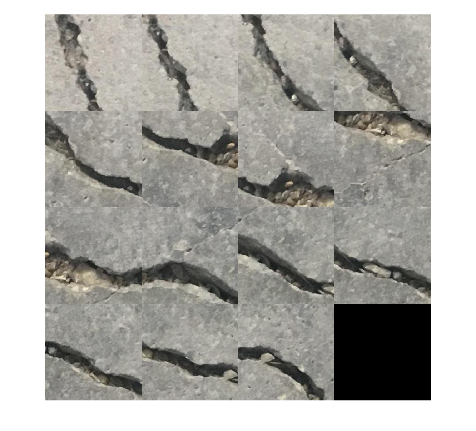

% Load images
dir = uigetdir("Title","Please select the Concrete Registration folder in your course files.");
imds = imageDatastore(dir);
montage(imds)

## Step 1 - Register Image Pairs

% Initialize all the transforms. Note that the rigid transform is used here  
% because the images are taken a fixed distance from the concr76ete.

% Initialize important variables
numImages = numel(imds.Files);
tforms(numImages) = rigid2d();
[sizeX,sizeY,~] = size(readimage(imds,1));

Iterate over the pairs of images to calculate the geometric transform and register them. You can uncomment the lines of code in the middle if you wanted to visually select control points for every pair of images instead of using the `registerConcreteImages` function.

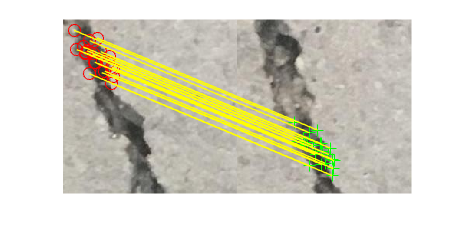

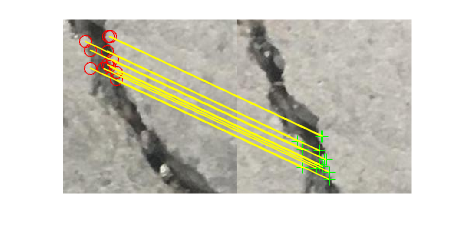

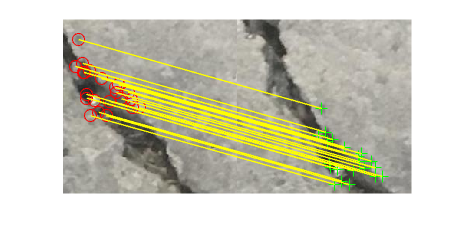

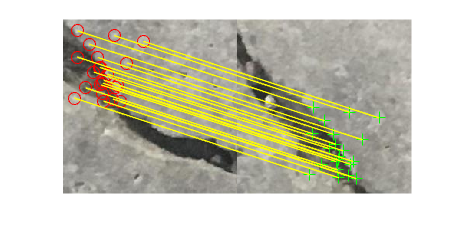

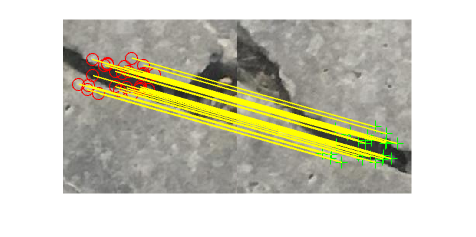

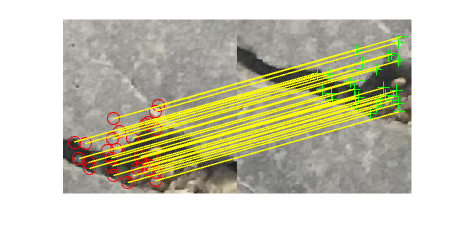

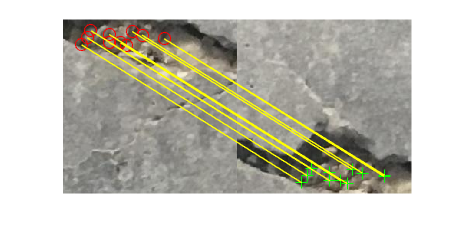

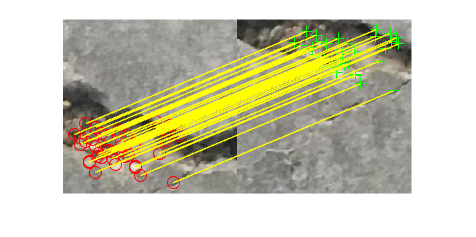

for i = 2:numImages       
    % Read images
    img1 = readimage(imds,i-1);
    img2 = readimage(imds,i);  
    
    % Use Registration Estimator App function to register images
    regOutput = registerConcreteImages(img2,img1);

%     % Visually select features to register images
%     [regOutput.MovingMatchedFeatures, regOutput.FixedMatchedFeatures] = ...
%         cpselect(img2,img1,"Wait",true);
%     regOutput.Transformation = estimateGeometricTransform2D(...
%         regOutput.MovingMatchedFeatures,regOutput.FixedMatchedFeatures,...
%         "rigid");

    figure
    showMatchedFeatures(img2,img1,regOutput.MovingMatchedFeatures,...
        regOutput.FixedMatchedFeatures,"montage")

    % Compute transforms
    tforms(i) = regOutput.Transformation;
    tforms(i).T = tforms(i).T * tforms(i-1).T; 
end

## Step 2 - Initialize the Template

Now, create an initial, empty, panorama into which all the images are placed.

Use the `outputLimits` function to compute the minimum and maximum output limits over all transformations. These values are used to automatically compute the size of the panorama.

for i = 1:numel(tforms)           
    [xlim(i,:),ylim(i,:)] = outputLimits(tforms(i),[1 sizeX],[1 sizeY]);
end

% Find the minimum and maximum output limits 
xMin = min(xlim(:));
xMax = max(xlim(:));
yMin = min(ylim(:));
yMax = max(ylim(:));

% Width and height of panorama.
imgWidth  = round(xMax - xMin);
imgHeight = round(yMax - yMin);

% Initialize the "empty" panorama.
panorama = zeros([imgHeight, imgWidth, 3],"uint8");

## Step 3 - Create the Panorama

Use `vision.AlphaBlender` to overlay the images together.

blender = vision.AlphaBlender("Operation","Binary mask","MaskSource","Input port");  

% Create a 2-D spatial reference object defining the size of the panorama
panoramaView = imref2d([imgHeight imgWidth],[xMin xMax],[yMin yMax]);

Use `imwarp` to place images onto the template.

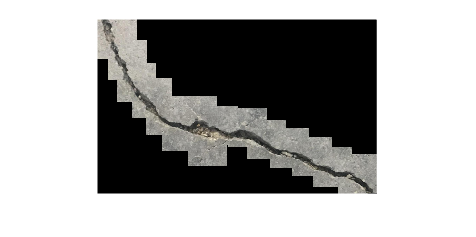

% Create the panorama
for i = 1:numImages
    img = readimage(imds,i);
   
    % Transform img into the panorama
    warpedImage = imwarp(img,tforms(i),"OutputView",panoramaView);
                  
    % Generate a binary mask.    
    mask = imwarp(true(size(img,[1 2])),tforms(i),"OutputView",panoramaView);
    
    % Overlay the warpedImage onto the panorama
    panorama = step(blender,panorama,warpedImage,mask);
end

imshow(panorama)

*Copyright 2022 The MathWorks, Inc.*